Nbits = 1e6;
in = randi([0, 1], [Nbits, 1])*2-1;

Transmitter

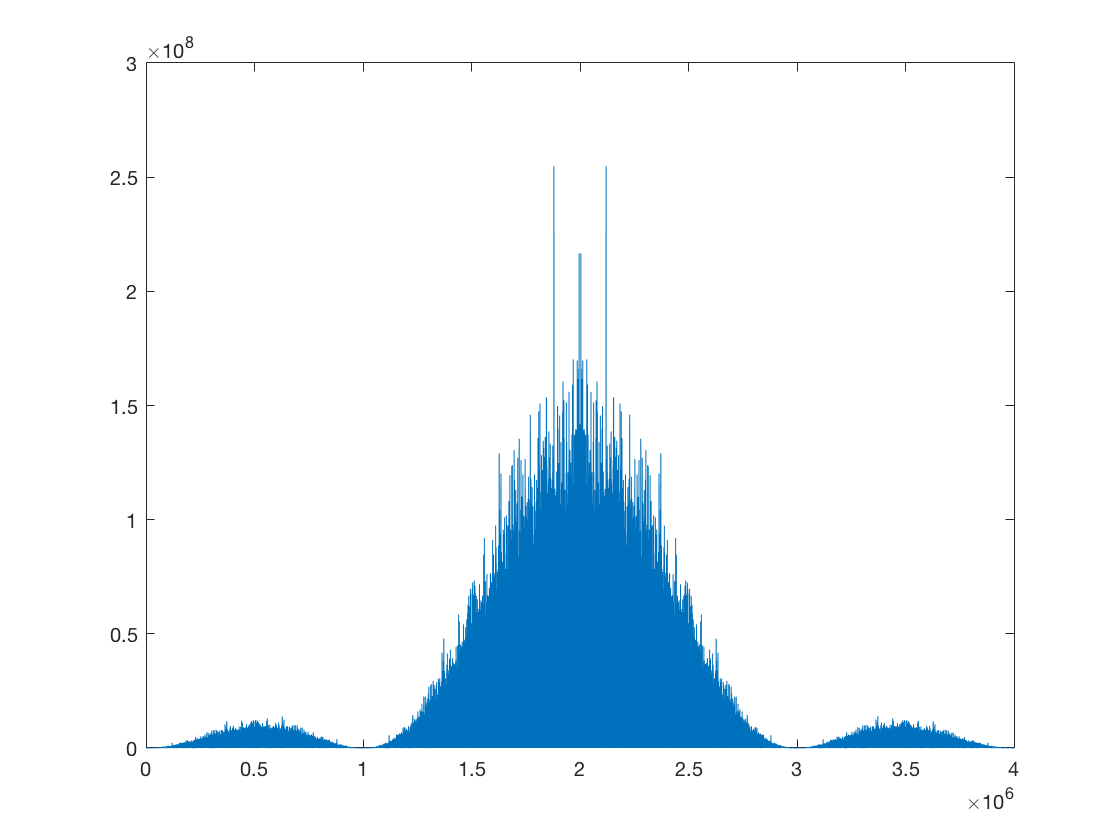

k = 2;
SpS = 2*k;
BpS = 1;
R_s = 1;
R_b = R_s * BpS;
B_sim = SpS * R_s;
v_t = zeros(Nbits*SpS, 1);
%Tc=1/R_s/SpS;
d_f = 1/Nbits;
f = (-(SpS/2):d_f:(SpS/2-d_f))';
f_p = 1.5;

% NRZ
for a=0:Nbits-1
    for b=1:SpS
        v_t(a*SpS+b) = in(a+1);
    end
end

figure(1)
plot(1:Nbits*SpS, fftshift(abs(fft(v_t)).^2))

Calcolo errori a diversi BER

err_arr = zeros(11, 1);

for www=2:12

Rumore Gaussiano Bianco

    EbN0 = (10^(www/10));
    P = mean(abs(in.^2));
    N0 = P/(EbN0*R_b);
    sigma = sqrt((N0/2)*B_sim);
    noise = sigma*randn(Nbits*SpS, 1);
    in_n = v_t+noise;

Filtro di Ricezione

    H_rx = 1./(1+1i*(f/f_p));
    X_f = fft(in_n);
    Y_f = H_rx .* X_f;
    y = ifft(Y_f);

Sampling & Decision

Vediamo su quale bit è meglio campionare

    BERs = zeros(SpS, 1);
    for bit = 1:SpS
        r = y(bit:SpS:end) > 0;
        r = 2*r-1;
        err = in ~= r;
        BERs(bit) = sum(err)/Nbits;
    end
    BERs
    [m, i] = min(BERs);
    i

Scegliamo di campionare sul bit i-esimo (è sempre il primo)

    r = y(i:SpS:end) > 0;
    r = 2*r-1;

Conteggio errori

    err = in ~= r;
    err_arr(www-1) = sum(err)/Nbits;
end

BERs =     0.2093
    0.3176
    0.3674
    0.4377


i = 1

BERs =     0.1921
    0.2998
    0.3537
    0.4308


i = 1

BERs =     0.1766
    0.2807
    0.3391
    0.4244


i = 1

BERs =     0.1623
    0.2622
    0.3238
    0.4163


i = 1

BERs =     0.1500
    0.2412
    0.3072
    0.4094


i = 1

BERs =     0.1379
    0.2217
    0.2915
    0.4025


i = 1

BERs =     0.1271
    0.2021
    0.2752
    0.3948


i = 1

BERs =     0.1159
    0.1836
    0.2594
    0.3870


i = 1

BERs =     0.1056
    0.1660
    0.2443
    0.3816


i = 1

BERs =     0.0959
    0.1509
    0.2290
    0.3751


i = 1

BERs =     0.0864
    0.1366
    0.2163
    0.3704


i = 1

Plotting

err_arr

err_arr =     0.2093
    0.1921
    0.1766
    0.1623
    0.1500
    0.1379
    0.1271
    0.1159
    0.1056
    0.0959


figure(2)
semilogy(2:12, err_arr, 'ro')
hold on

Andamento teorico

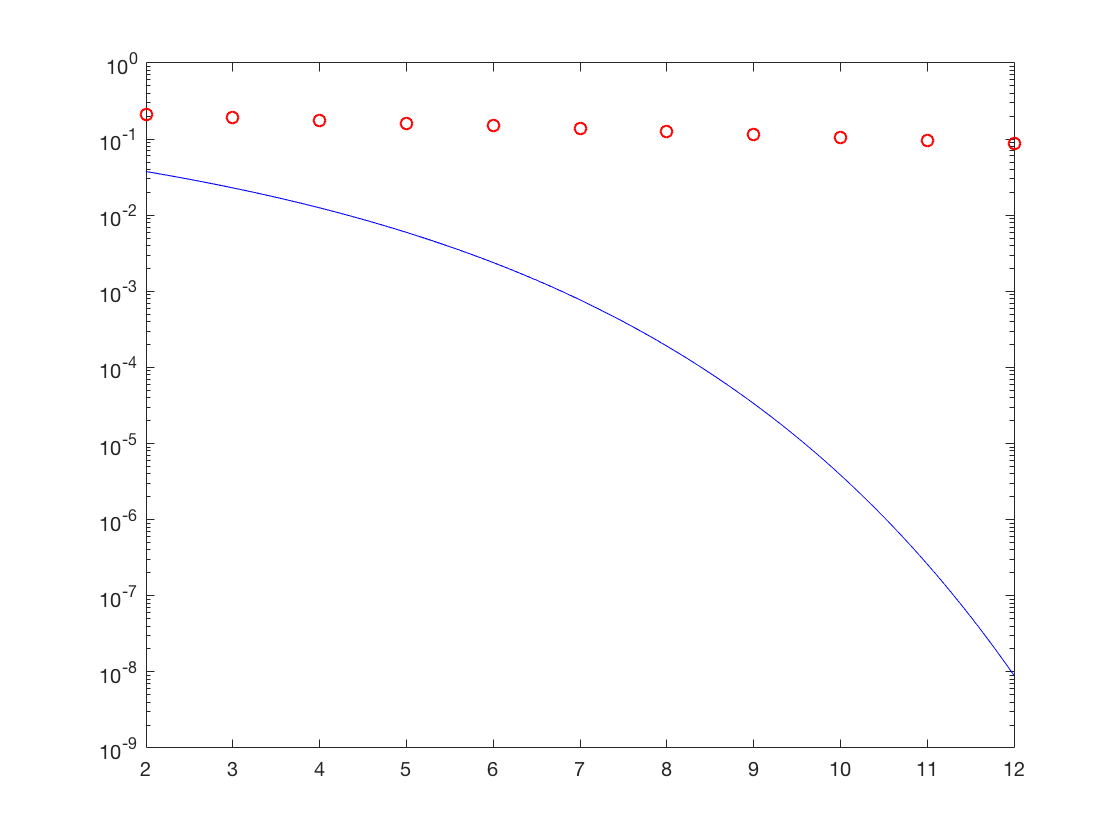

EbN0 = 2:0.1:12;
BER = 0.5*erfc(sqrt(10.^(EbN0/10)));
semilogy(EbN0, BER, 'b-')

Diagramma ad occhio

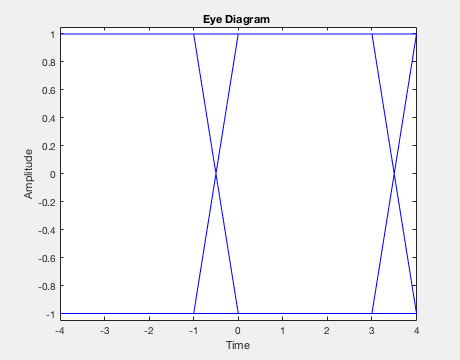

figure(3)
eyediagram(v_t(1:2000*SpS), 2*SpS, 2*SpS);

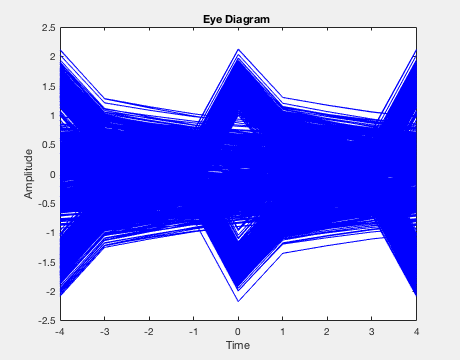



X_f_nn = fft(v_t);
Y_f_nn = H_rx .* X_f_nn;
y_nn = real(ifft(Y_f_nn));
figure(4)
eyediagram(y_nn(1:2000*SpS), 2*SpS, 2*SpS);